# Main Inner loop sysytem for the rhino motors consisting of the Zeigler nichols methods and the different relational parametric terms needed for efficient tuning of the motors.

% ------------- Motor parameters/ mechanical metrics ~~~~~~~~~~~~~~~~~~~~~
Rm = 1.6;      % Armature Resistance(Ohm)
Lm = 0.001;    % Inductance(Henry)
K = 0.00636;  % Motor constant( V/rad)
Bm = 2.7e-6;   % Viscous friction of the motor at no load)
N = 52.1;          % gear ratio(as present in the documentation of the motor)

% -------------------- Robot physical parameters -----------------
% Physical parameters
m_wheel = 0.5;              % kg (wheel only)
m_robot_total = 20;        % kg ← need this number
r_wheel = 0.0625;           % m

g = 9.81;
eta_gearbox = 0.75;  % efficiency of the gearbox of the motor(general)
mu_rr = 0.05;        % rotational resistance of the meccanum wheel on the wooden ply.

% Calculation of the inertia of the wheel and the robot
J_wheel_rot = 0.5 * m_wheel * r_wheel^2;
J_robot_lin = (m_robot_total/4) * r_wheel^2;
J_rotor = 2.5e-6;
J_wheel_reflected = J_wheel_rot/N^2;
J_robot_reflected = J_robot_lin/N^2;
Jm = J_rotor + J_wheel_reflected + J_robot_reflected;

% Calculation of the rolling resistance.
F_rr_total      = mu_rr * m_robot_total * g;
F_rr_per_wheel  = F_rr_total / 4;
tau_rr_wheel    = F_rr_per_wheel * r_wheel;
tau_rr_motor    = tau_rr_wheel / (N * eta_gearbox);
omega_wheel_op  = 25;                    % nominal operating wheel speed (rad/s)
omega_motor_op  = omega_wheel_op * N;
B_rr_equiv      = tau_rr_motor / omega_motor_op;
B_total         = Bm + B_rr_equiv;       % we'll be using this in the transfer function

% Motor driver supply and limit
V_supply = 12; % voltage by the motor driver
PWM_max = 255; % for the 8 bit signed in the motor driver.
V2DCB = PWM_max/V_supply;
DCB2V = V_supply/PWM_max;
sat_limit = V_supply;  % this is the saturation limit to the motor

% Calculating the encoder inputs
TS= 0.001; % taling the arduino due defaulkt 1Khz interupt pin clock
CPR            = 2700;
RAD2C_gain     = CPR / (2*pi);           % 461.86 counts/rad
C2RAD_TS_gain  = (2*pi / CPR) / TS;   % 2.165 rad/s per count/sample (TS=1ms)

% Loop gainb
Lgain = 1/N;

sim_stop_time = 10;
sim_step_time = TS;
ref_speed = 25; % (rad/sec)



## Using the Zeigler Nichols method to find out the minimum PID value or the gain for the system.

% --------------- Plant side function (motor-side speed/ voltage)----------
num = K;
den = [Jm*Lm,  Jm*Rm + B_total*Lm,  B_total*Rm + K^2];
G_motor = tf(num,den);

% WHeel side plant function
G_plant = G_motor * (1/N);

%% ===== Z-N ultimate-gain on the *discrete* plant with delay =====
G_plant_d = c2d(G_plant, TS, 'zoh');
% Add one sample of computational delay (firmware reads encoder, computes, writes PWM next cycle)
G_plant_d_delayed = G_plant_d * tf(1, [1 0], TS);

[Gm, ~, Wcg, ~] = margin(G_plant_d_delayed);

if isinf(Gm) || Wcg == 0
    error('Even discrete plant has infinite gain margin. Use step-response tuning instead.');
end

Ku = Gm;
Tu = 2*pi / Wcg;

% Z-N classic PID
Kp_zn = 0.6  * Ku;
Ti_zn = 0.5  * Tu;
Td_zn = 0.125 * Tu;
Ki_zn = Kp_zn / Ti_zn;
Kd_zn = Kp_zn * Td_zn;

% Z-N "no-overshoot" — conservative starting point
Kp = 0.2 * Ku;
Ki = Kp / (0.5 * Tu);
Kd = Kp * (Tu / 3);

fprintf('Discrete Z-N: Ku=%.4f, Tu=%.4f s\n', Ku, Tu);

Discrete Z-N: Ku=112.8619, Tu=0.0083 s


fprintf('Conservative gains:  Kp=%.4f  Ki=%.4f  Kd=%.6f\n', Kp, Ki, Kd);

Conservative gains:  Kp=22.5724  Ki=5441.3584  Kd=0.062425


fprintf('Aggressive gains:    Kp=%.4f  Ki=%.4f  Kd=%.6f\n', Kp_zn, Ki_zn, Kd_zn);

Aggressive gains:    Kp=67.7172  Ki=16324.0751  Kd=0.070228


## Executing the simulation and plotting the result

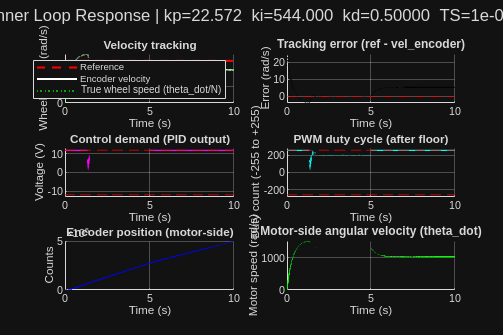

kp =22.5724 ; ki = 544; kd = 0.5;

% Reset model state
set_param('internal_loop', 'LoadInitialState', 'off');
set_param('internal_loop', 'SaveFinalState', 'off');

% Run simulation (variables Kp, Ki, Kd, TS, ref_speed, etc. are pulled from workspace)
sim('internal_loop.slx');



%% ===== Plot all signals from inner loop simulation =====
figure('Name','Inner Loop Diagnostics','Position',[100 100 1200 800]);

% --- Subplot 1: Velocity tracking (the main result) ---
subplot(3,2,1); hold on; grid on;
plot([0 tsim(end)], [ref_speed ref_speed], 'r--', 'LineWidth', 1.5);
plot(tsim, vel_encoder, 'w', 'LineWidth', 1.5);
plot(tsim, theta_dot/N, 'g:', 'LineWidth', 1.0);
xlabel('Time (s)');
ylabel('Wheel speed (rad/s)');
title('Velocity tracking');
legend('Reference','Encoder velocity','True wheel speed (theta\_dot/N)', ...
       'Location','southeast');

% --- Subplot 2: Error signal ---
subplot(3,2,2); hold on; grid on;
plot(tsim, err, 'k', 'LineWidth', 1.2);
yline(0,'r--');
xlabel('Time (s)');
ylabel('Error (rad/s)');
title('Tracking error (ref - vel\_encoder)');

% --- Subplot 3: Control voltage ---
subplot(3,2,3); hold on; grid on;
plot(tsim, control_demand, 'm', 'LineWidth', 1.2);
yline( sat_limit, 'r--', 'LineWidth', 0.8);
yline(-sat_limit, 'r--', 'LineWidth', 0.8);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Control demand (PID output)');
ylim([-V_supply*1.1, V_supply*1.1]);

% --- Subplot 4: Duty cycle command ---
subplot(3,2,4); hold on; grid on;
plot(tsim, control_dutycycles, 'c', 'LineWidth', 1.2);
yline( PWM_max, 'r--', 'LineWidth', 0.8);
yline(-PWM_max, 'r--', 'LineWidth', 0.8);
xlabel('Time (s)');
ylabel('Duty count (-255 to +255)');
title('PWM duty cycle (after floor)');
ylim([-PWM_max*1.1, PWM_max*1.1]);

% --- Subplot 5: Encoder counts ---
subplot(3,2,5); hold on; grid on;
plot(tsim, pos_counts, 'b', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Counts');
title('Encoder position (motor-side)');

% --- Subplot 6: Motor-side angular velocity ---
subplot(3,2,6); hold on; grid on;
plot(tsim, theta_dot, 'g', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Motor speed (rad/s)');
title('Motor-side angular velocity (theta\_dot)');

sgtitle(sprintf('Inner Loop Response | kp=%.3f  ki=%.3f  kd=%.5f  TS=%.0e', ...
    kp, ki, kd, TS));


%% ===== Print key metrics to console =====
fprintf('\n========= Inner Loop Performance =========\n');


========= Inner Loop Performance =========


fprintf('Reference speed:        %.2f rad/s\n', ref_speed);

Reference speed:        25.00 rad/s


fprintf('Final encoder velocity: %.2f rad/s\n', vel_encoder(end));

Final encoder velocity: 19.70 rad/s


fprintf('Steady-state error:     %.4f rad/s\n', ref_speed - vel_encoder(end));

Steady-state error:     5.3022 rad/s


fprintf('Final control voltage:  %.2f V (limit: %.1f V)\n', control_demand(end), sat_limit);

Final control voltage:  12.00 V (limit: 12.0 V)


fprintf('Final duty cycle:       %d (limit: %d)\n', round(control_dutycycles(end)), PWM_max);

Final duty cycle:       255 (limit: 255)


fprintf('Saturation hit:         %s\n', ...
    string(any(abs(control_demand) >= sat_limit*0.99)));

Saturation hit:         true



% Step response metrics (only if the system rises)
y = vel_encoder;
y_final = mean(y(end-100:end));
if y_final > 0.5*ref_speed
    % Rise time (10% to 90%)
    t10 = tsim(find(y >= 0.1*y_final, 1));
    t90 = tsim(find(y >= 0.9*y_final, 1));
    rise_time = t90 - t10;
    
    % Overshoot
    [y_max, ~] = max(y);
    overshoot = max(0, (y_max - y_final)/y_final * 100);
    
    % Settling time (within 2% of final)
    settling_idx = find(abs(y - y_final) > 0.02*y_final, 1, 'last');
    if isempty(settling_idx)
        settling_time = 0;
    else
        settling_time = tsim(settling_idx);
    end
    
    fprintf('\n--- Step response metrics ---\n');
    fprintf('Rise time (10-90%%):     %.4f s\n', rise_time);
    fprintf('Overshoot:              %.2f %%\n', overshoot);
    fprintf('Settling time (2%%):     %.4f s\n', settling_time);
end


--- Step response metrics ---


Rise time (10-90%):     0.2740 s


Overshoot:              47.65 %


Settling time (2%):     5.8630 s


fprintf('==========================================\n\n');

## Checking for the disturbances

% Now i will be decreasing some voltage before the motor and then test it.
% I have added a step of 1.26 volts with a smaple time of -1 and step time
% of 5 secs. The step is added after the DCB2V block and between the motor
% model making a voltage dip of 1.26 volt and a workspace disturbance is
% added to it to mark the change in the output.
